Q1

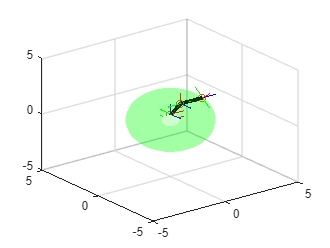

L0 = 0.5;
L1 = 1;
L2 = 1.5; 
% Input joint angles in degrees
% joint_angles = [90, 90, 60, 90, 90, 60];
joint_angles = [0,pi/4,-pi/4,pi/4,0,0];
figure;
[T, result] = forward_kinematics(joint_angles,L0,L1,L2);
plot_man(T,gcf);


% dh = [joint_angles(1), L0, 0, -pi/2 ;
%       joint_angles(2) - pi/2, 0, L1, 0 ;
%       joint_angles(3) + pi/2, 0, L2, 0;
%       joint_angles(4) + pi, 0 , 0, 0;
%       joint_angles(5) + pi, 0 , L4, 0 ;
%       joint_angles(6), 0, L5, 0;];
for i = 1:6
    fprintf('Transformation matrix: \n');
    disp(squeeze(T(i, :, :)));
    fprintf('\n');
end

Transformation matrix: 


    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.5000
         0         0         0    1.0000



Transformation matrix: 


    0.7071   -0.7071         0         0
    0.0000    0.0000   -1.0000         0
    0.7071    0.7071    0.0000         0
         0         0         0    1.0000



Transformation matrix: 


    0.7071   -0.7071         0    1.0000
    0.7071    0.7071         0         0
         0         0    1.0000         0
         0         0         0    1.0000



Transformation matrix: 


   -0.7071    0.7071         0         0
   -0.0000   -0.0000   -1.0000   -1.5000
   -0.7071   -0.7071    0.0000    0.0000
         0         0         0    1.0000



Transformation matrix: 


   -1.0000   -0.0000         0         0
    0.0000   -0.0000   -1.0000         0
    0.0000   -1.0000    0.0000         0
         0         0         0    1.0000



Transformation matrix: 


    1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000




disp(result);

    0.0000   -0.0000    1.0000    2.2071
   -0.7071   -0.7071    0.0000   -0.0000
    0.7071   -0.7071   -0.0000    1.2071
         0         0         0    1.0000



Trajectory of the ball

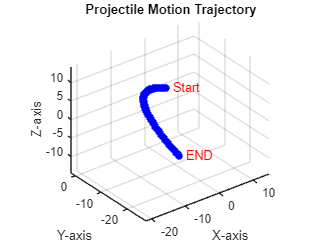

clear;
clc;
initial_position = [5, 0, 0];
initial_velocity = 8;
launch_angle = 135;

launch_angle_rad = deg2rad(launch_angle);

t_div = 100;
t = linspace(0, 3, t_div);

% Parametric equations for projectile motion
x = initial_position(1) + initial_velocity * cos(launch_angle_rad) * t;
y = initial_position(2) + initial_velocity * sin(launch_angle_rad) * t - 0.5 * 9.81 * t.^2;
z = initial_position(3); % g = 9.81 m/s^2

figure;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Projectile Motion Trajectory');
grid on;
axis equal;

% Mark the starting point and ending point
hold on;
scatter3(initial_position(1), initial_position(2), initial_position(3), 'r', 'filled');
text(initial_position(1), initial_position(2), initial_position(3), '  Start', 'Color', 'r');

scatter3(x(end), y(end), z(end), 'r', 'filled');
text(x(end), y(end), z(end), '  END', 'Color', 'r');

trajectory = animatedline('LineWidth', 2);

view(3);

for i = 1:length(t)
    x_current = initial_position(1) + initial_velocity * cos(launch_angle_rad) * t(i);
    y_current = initial_position(2) + initial_velocity * sin(launch_angle_rad) * t(i) - 0.5 * 9.81 * t(i)^2;
    z_current = initial_position(3); % g = 9.81 m/s^2
    
    
    addpoints(trajectory, x_current, y_current, z_current);
    scatter3(x_current, y_current, z_current, 'b', 'filled');
    
    pause(1/t_div);
   
    drawnow;
end

hold off;